% considering 12 state variables for the system 
% The first 6 are actual variables and the other 6 are estimated variables
% which are used to compute the error between the estimated state and true
% state.

% State variables  = [x x_dot theta1 theta1_dot theta2 theta2_dot Estimated_variables] 

% Initial conditions for luenberger observer
X_i = [0, 0, 10, 0, 15, 0, 0, 0, 0, 0, 0, 0];

Poles_placements = [-0.5; -1; -2; -2.5; -3.5; -4.5]

Poles_placements =    -0.5000
   -1.0000
   -2.0000
   -2.5000
   -3.5000
   -4.5000



% computing the gain matrix using the lqr controller function
K_matrix =lqr(A,B,Q,R);

% computing the luenberger matrix for all the output vector conditions
% which are observable
L1 = place(A',C_01',Poles_placements)' 

L1 =    14.0000
   74.3814
 -160.8343
  162.8432
  -22.2329
 -318.2588


L3 = place(A',C_03',Poles_placements)'

L3 =     8.2735    1.8102
   20.8628    9.5757
  -15.5887  -16.2526
    5.8626   -0.6985
    0.5281    5.7265
    2.0580    7.0962


L4 = place(A',C_04',Poles_placements)'

L4 =     6.7691    0.5147    0.0000
   10.5617    0.4905   -0.9809
    0.5635    5.7309    0.0000
    1.6443    7.1457   -0.0490
    0.0000    0.0000    1.5000
    0.0000   -0.0981   -0.5791



% for output vectors x(t)
% Luenberger A matrix
Ac_1 = [(A-(B*K_matrix)) (B*K_matrix); 
        zeros(size(A)) (A-(L1*C_01))];
% Luenberger B matrix
Bc = [B;zeros(size(B))];
% Luenberger C matrix
Cc_1 = [C_01 zeros(size(C_01))];

% for output vectors x(t) theta(2)
Ac_3 = [(A-B*K_matrix) B*K_matrix;
        zeros(size(A)) (A-L3*C_03)];
% Luenberger C matrix
Cc_3 = [C_03 zeros(size(C_03))];

% for output vectors x(t) theta(1) theta(2)
% Luenberger A matrix
Ac_4 = [(A-B*K_matrix) B*K_matrix;
        zeros(size(A)) (A-L4*C_04)];
% Luenberger C matrix
Cc_4 = [C_04 zeros(size(C_04))];

% Initial and step response for linearsystem1
disp("Linear System 1")

Linear System 1


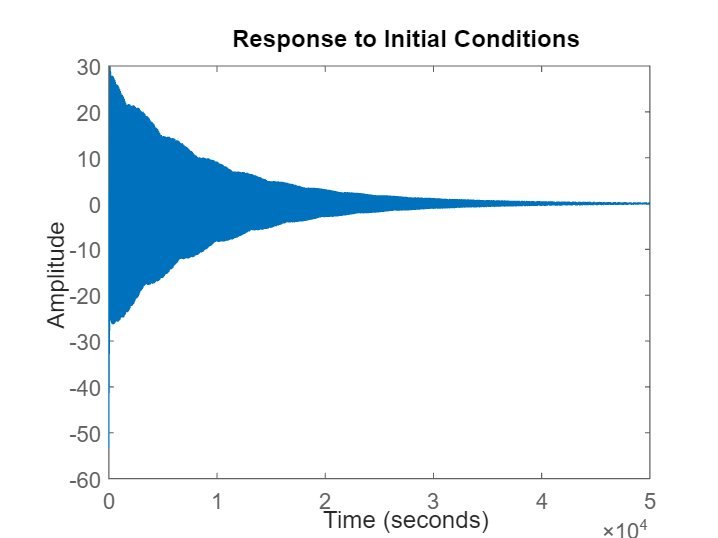

linearSystem_1 = ss(Ac_1, Bc, Cc_1,D);
figure 
initial(linearSystem_1,X_i)

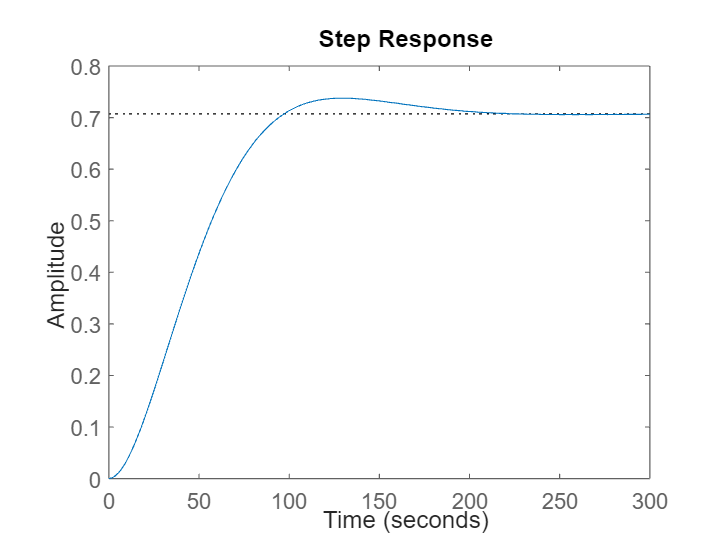

figure
step(linearSystem_1)


% Initial and step response for linearsystem3
disp("Linear System 3")

Linear System 3


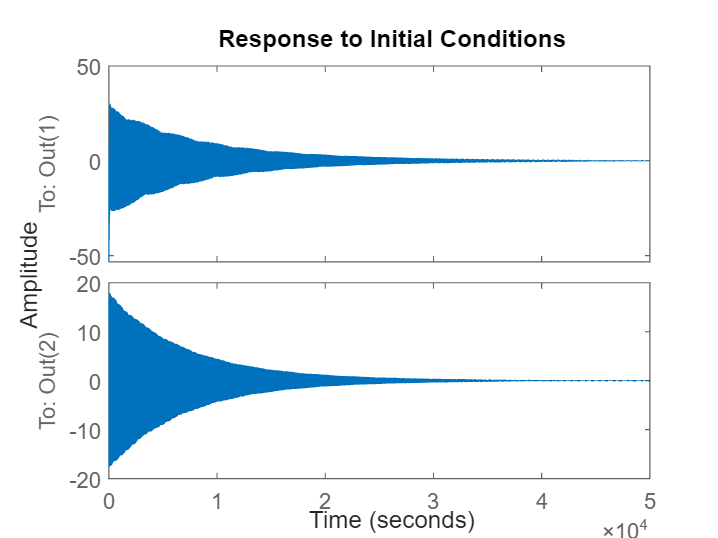

linearSystem_3 = ss(Ac_3, Bc, Cc_3,D);
figure
initial(linearSystem_3,X_i)

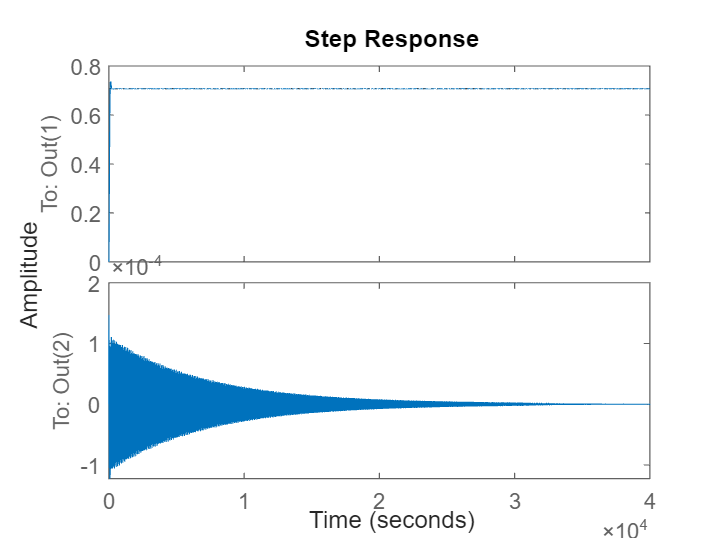

figure
step(linearSystem_3)


% Initial and step response for linearsystem4
disp("Linear System 4")

Linear System 4


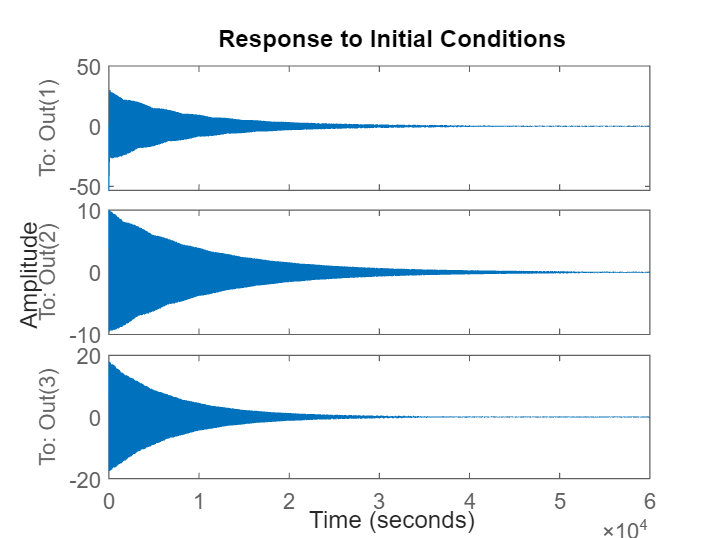

linearSystem_4 = ss(Ac_4, Bc, Cc_4, D);
figure
initial(linearSystem_4,X_i)

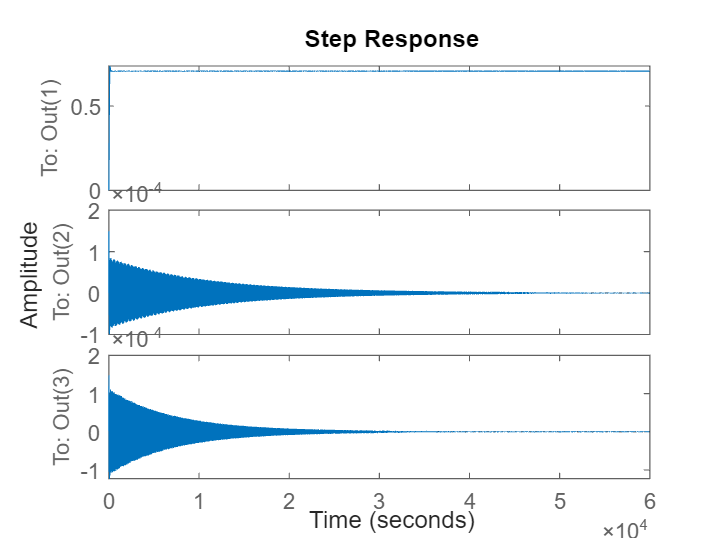

figure
step(linearSystem_4)


% Non-linear Sysytems
disp("Non linear systems")

Non linear systems



% A matrix for the non linear system
A_nl=[0 1 0 0 0 0;
      0 0 -(m1*g)/M 0 -(m2*g)/M 0;
      0 0 0 1 0 0;
      0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
      0 0 0 0 0 1;
      0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];
% B matrix for the non linear system
B_nl = [0; 
        1/M;
        0;
        1/(M*l1);
        0;
        1/(M*l2)];

% Considering the systems with outputvectors which are observable

% Computing the gain matrix using the lqr function for the non-linear
% system
K_matrix =lqr(A_nl,B_nl,Q,R);

% computing the luenberger matrix for all the output vector conditions
% which are observable for non-linear systems
L1 = place(A_nl',C_01',Poles_placements)' 

L1 =    14.0000
   74.3814
 -160.8343
  162.8432
  -22.2329
 -318.2588


L3 = place(A_nl',C_03',Poles_placements)' 

L3 =     8.2735    1.8102
   20.8628    9.5757
  -15.5887  -16.2526
    5.8626   -0.6985
    0.5281    5.7265
    2.0580    7.0962


L4 = place(A_nl',C_04',Poles_placements)' 

L4 =     6.7691    0.5147    0.0000
   10.5617    0.4905   -0.9809
    0.5635    5.7309    0.0000
    1.6443    7.1457   -0.0490
    0.0000    0.0000    1.5000
    0.0000   -0.0981   -0.5791


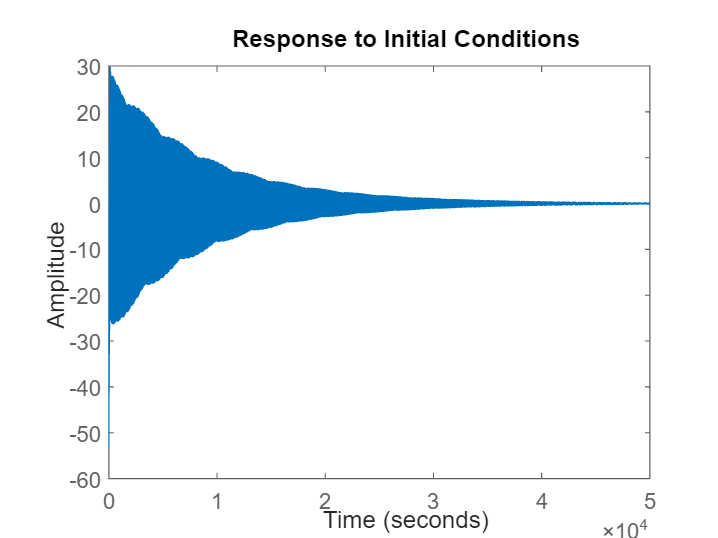


% for output vectors x(t)
% Luenberger A matrix
Ac_1 = [(A_nl-B_nl*K_matrix) B_nl*K_matrix; 
        zeros(size(A_nl)) (A_nl-L1*C_01)];
% Luenberger B matrix
Bc = [B_nl;zeros(size(B_nl))];
% Luenberger C matrix
Cc_1 = [C_01 zeros(size(C_01))];

% for output vectors x(t) theta(2)
% Luenberger A matrix
Ac_3 = [(A_nl-B_nl*K_matrix) B_nl*K_matrix;
        zeros(size(A_nl)) (A_nl-L3*C_03)];
% Luenberger C matrix
Cc_3 = [C_03 zeros(size(C_03))];

% for output vectors x(t) theta(1) theta(2)
% Luenberger A matrix
Ac_4 = [(A_nl-B_nl*K_matrix) B_nl*K_matrix;
        zeros(size(A_nl)) (A_nl-L4*C_04)];
% Luenberger C matrix
Cc_4 = [C_04 zeros(size(C_04))];

% Initial and step response for non-linearsystem1
nonLinearSystem_1 = ss(Ac_1, Bc, Cc_1,D);
figure
initial(nonLinearSystem_1,X_i)

figure
step(nonLinearSystem_1)


% Initial and step response for non-linearsystem3
nonLinearSystem_3 = ss(Ac_3, Bc, Cc_3,D);
figure
initial(nonLinearSystem_3,X_i)

figure
step(nonLinearSystem_3)


% Initial and step response for non-linearsystem4
nonLinearSystem_4 = ss(Ac_4, Bc, Cc_4, D);
figure
initial(nonLinearSystem_4,X_i)

figure
step(nonLinearSystem_4)